# Melt-pool dynamics -- system identification for bulky cube

## 1.Data Preparing

### Read the data from txt file, retrieve timestamp, minor axix, laser power and velocity value

- Create data objects to represent data.

- Plot the data object. 

### **load experiment data into workspace**( time-domain data from a steady-state that laser power was perturbed from equilibrium values). --step test

***load 2 or more experiment data --> one for system identification, the other for verification***

***display the content of the text file, to check if file can be read***

% type('test_data.txt'); % melt-pool width
% type('power_data.txt');
% type('velocity_data.txt')
type('../Meltpool_data/step_20_20_cube_laser_on.csv')

field.header.stamp,time,field.major_axis,field.minor_axis,field.orientation,field.x,field.y,,field.header.stamp,time,field.value,,field.header.stamp,field.speed,field.vx,field.vy,field.vz
1.59162354877295E+018,0,90.6888961792,61.957408905,-0.0926407203078,397.777526855,252.684295654,,1.59162354874056E+018,0,2.20000004768,,1.59162354876816E+018,0.0245999991894,-0.0122600002214,-0.0213699992746,-4.00E-05
1.59162354880839E+018,0.035442432,81.669593811,70.0693206787,-0.235740616918,396.000213623,253.808944702,,1.59162354877295E+018,0.032389888,2.20000004768,,1.59162354882834E+018,0.0245999991894,-0.0122899999842,-0.0213099997491,3.00E-05
1.5916235488421E+018,0.06915072,85.1706619263,70.9341964722,-0.108892664313,397.369110107,255.268356323,,1.59162354880839E+018,0.06783232,2.20000004768,,1.59162354889076E+018,0.0244999993593,-0.0122199999169,-0.0212500002235,3.00E-05
1.59162354886898E+018,0.096029952,84.4154281616,71.2225341797,-0.124668560922,396.476989746,254.495513916,,1.5916235488421E+

**store all the data into a table (the names are changed for matlab format)**

% experiment data 1
table_meltpool = readtable('../Meltpool_data/step_20_20_cube_laser_on.csv', ...
       'Delimiter', ',' ,'ReadVariableNames',true)

table_meltpool = 7984×17 table
    field_header_stamp      time      field_major_axis    field_minor_axis    field_orientation    field_x    field_y    Var8    field_header_stamp_1     time_1     field_value    Var12    field_header_stamp_2    field_speed    field_vx    field_vy    field_vz
    __________________    ________    ________________    ________________    _________________    _______    _______    ____    ____________________    ________    ___________    _____    __________________

%table_power = readtable('Layer3_power.txt', ...
%       'Delimiter', ',' ,'ReadVariableNames',true); 

% for experiment data 2
%table_meltpool2 = readtable('Layer3.txt', ...
%       'Delimiter', ',' ,'ReadVariableNames',true); 
%table_power2 = readtable('Layer3_power.txt', ...
%       'Delimiter', ',' ,'ReadVariableNames',true); 

#### Extract the data according to their name 

time = table_meltpool{:, 'time'};
minorAxis = table_meltpool{:, 'field_minor_axis'};
laserPower = table_meltpool{:, 'field_value'};
velocity = table_meltpool{:, 'field_speed'};

% for experiment data 2 对照组
%timeStamp2 = table_meltpool2{:, 'field_header_stamp'};
%minorAxis2 = table_meltpool2{:, 'field_minor_axis'};
%laserPower2 = table_power2{:, 'field_power'};

## 2. Plot data for simple visualization

**Plot the melt-pool width (minor axis) and laser power agiainst timestamp**

**for ****open loop****:**

- **input: laser power**

- **output: melt-pool width**

[](https://www.mathworks.com/help/control/ref/connect.html)

**Plotting the Input/Output Data**

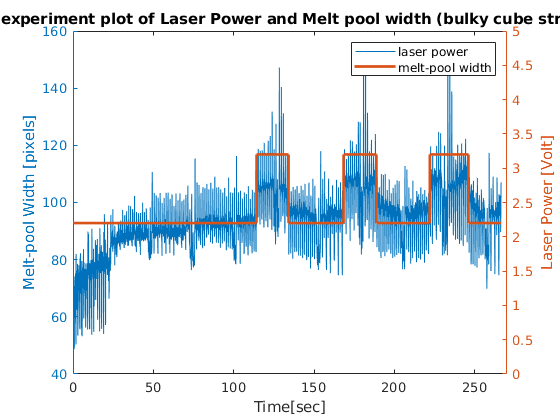

% for experiment data 1----------------------------------------
figure
yyaxis left
plot(time, minorAxis);
yyaxis right
plot(time, laserPower,'LineWidth',2);
% add titles and lables
yyaxis left
title('Step experiment plot of Laser Power and Melt pool width (bulky cube structure)')
xlabel('Time[sec]')
ylabel('Melt-pool Width [pixels]')
yyaxis right
ylabel('Laser Power [Volt]')


legend('laser power','melt-pool width')
xlim([0.0 270.0])
ylim([0.0 5.0])




%xlim([1582856500000000000 1582856850000000000])
%ylim([0 250])

% for experiment data 2-------------------------------------------
% figure
% yyaxis left
% plot(timeStampe2, laserPower2);
% yyaxis right
% plot(timeStamp2, minorAxis2);
% % add titles and lables
% yyaxis left
% title('Plots of Laser Power and Melt-pool width (20 layers)')
% xlabel('TimeStamp')
% ylabel('Melt-pool Width [pixels]')
% 
% yyaxis right
% ylabel('Laser Power [Volt]')
% 
% legend('laser power','melt-pool width')



%xlim([1582856500000000000 1582856850000000000])
%ylim([0 250])

**Extract the single step change**

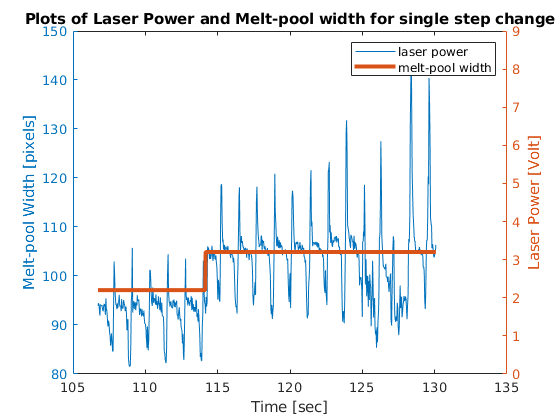

time_track= time(3200:3900);
minorAxis_track = minorAxis(3200:3900);
laserPower_track = laserPower(3200:3900);

figure
yyaxis left
plot(time_track, minorAxis_track);
yyaxis right
plot(time_track, laserPower_track,'LineWidth',3);
% add titles and lables
yyaxis left
title('Plots of Laser Power and Melt-pool width for single step change')
xlabel('Time [sec]')
ylabel('Melt-pool Width [pixels]')
yyaxis right
ylabel('Laser Power [Volt]')

legend('laser power','melt-pool width')
ylim([0 9])

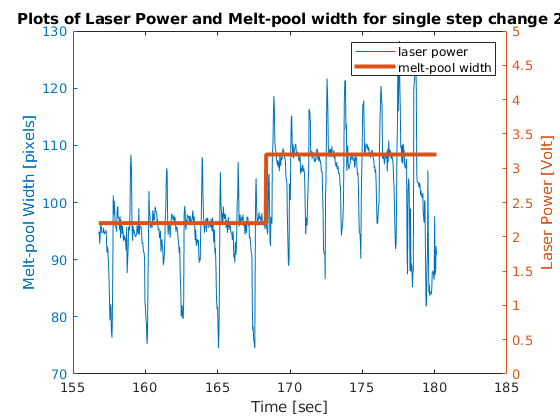


% For the second step test 
time_track2= time(4700:5400);
minorAxis_track2 = minorAxis(4700:5400);
laserPower_track2 = laserPower(4700:5400);

figure
yyaxis left
plot(time_track2, minorAxis_track2);
yyaxis right
plot(time_track2, laserPower_track2,'LineWidth',3);
% add titles and lables
yyaxis left
title('Plots of Laser Power and Melt-pool width for single step change 2')
xlabel('Time [sec]')
ylabel('Melt-pool Width [pixels]')
yyaxis right
ylabel('Laser Power [Volt]')

legend('laser power','melt-pool width')
ylim([0 5])

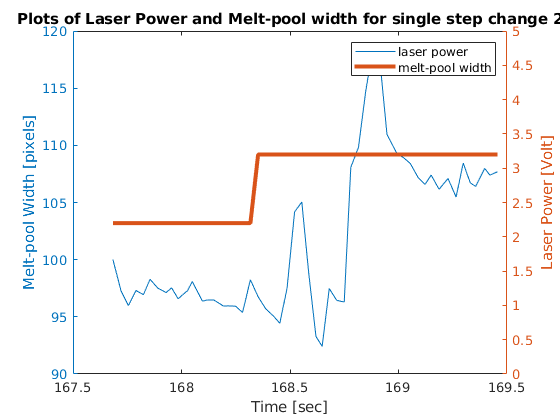

% For the second step test 
time_track_test= time(5027:5080);
minorAxis_track_test = minorAxis(5027:5080);
laserPower_track_test = laserPower(5027:5080);

figure
yyaxis left
plot(time_track_test, minorAxis_track_test);
yyaxis right
plot(time_track_test, laserPower_track_test,'LineWidth',3);
% add titles and lables
yyaxis left
title('Plots of Laser Power and Melt-pool width for single step change 2')
xlabel('Time [sec]')
ylabel('Melt-pool Width [pixels]')
yyaxis right
ylabel('Laser Power [Volt]')

legend('laser power','melt-pool width')
ylim([0 5])

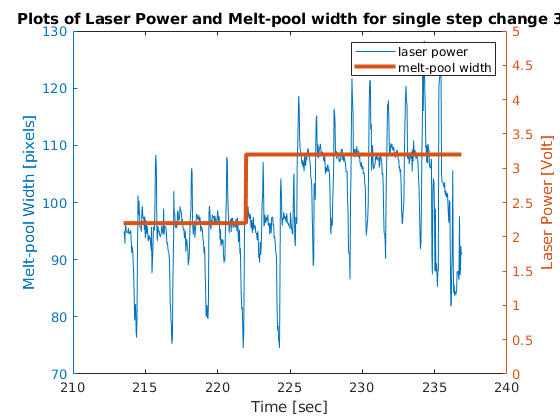


% For the third step test 
time_track3= time(6400:7100);
minorAxis_track3 = minorAxis(6400:7100);
laserPower_track3 = laserPower(6400:7100);

figure
yyaxis left
plot(time_track3, minorAxis_track2);
yyaxis right
plot(time_track3, laserPower_track3,'LineWidth',3);
% add titles and lables
yyaxis left
title('Plots of Laser Power and Melt-pool width for single step change 3')
xlabel('Time [sec]')
ylabel('Melt-pool Width [pixels]')
yyaxis right
ylabel('Laser Power [Volt]')

legend('laser power','melt-pool width')
ylim([0 5])

# Identify Linear Models in the Command Line

## Data Preparing

#### Estimate and validate linear models from single-input/single-output (SISO) data to find the one that best describes the system dynamics.

- Process data by removing offsets from the input and output signals.

- Estimate and validate linear models from the data.

- Simulate and predict model output.

**Removing Equilibrium Values from the Data**

the inputs and the outputs have nonzero equilibrium values, subtract the mean values from each signal: seek models around zero without modeling the absolute equilibrium levels in physical units.

%---------------from example--------------------------
%Input_exp1 = Input_exp1-...
%   ones(size(Input_exp1,1),1)*mean(Input_exp1(1:50,:));
%Output_exp1 = Output_exp1-...
%   mean(Output_exp1(1:50,:));
%Input_exp2 = Input_exp2-...
%   ones(size(Input_exp2,1),1)*mean(Input_exp2(1:50,:));
%Output_exp2 = Output_exp2-...
%   mean(Output_exp2(1:50,:));
%----------------------------------------------------
% experiment data 1
laserPower = laserPower - mean(laserPower(1:50,:)); % open loop input
minorAxis = minorAxis - mean(minorAxis(1:50,:)); % open loop outloop
% experiment data 2
laserPower2 = laserPower2 - mean(laserPower2(1:50,:)); % open loop input

Unrecognized function or variable 'laserPower2'.

minorAxis2 = minorAxis2 - mean(minorAxis2(1:50,:)); % open loop outloop

**Using Objects to Represent Data for System Identification**

[iddata](https://www.mathworks.com/help/ident/ref/iddata.html#mw_f757274e-b4eb-4f57-8035-f4fc4b688a68)***: ***Input-output data and its properties for system identification in the time or frequency domain

***idfrd:*** Frequency-response data or model: 

`syntax: `[`data = iddata(y,u,Ts)`](https://www.mathworks.com/help/ident/ref/iddata.html#d118e54376)` --> create a data object`

Ts = 1/30; % Sampling time is 1/30s --> corresponds to sampling rate at 30 Hz, set by ROS publisher
% ze = iddata(Output_exp1,Input_exp1,Ts); --example format
OpenLoop_system1 = iddata(minorAxis,laserPower,Ts); % for experiment1 data
OpenLoop_system2 = iddata(minorAxis2,laserPower2,Ts); % for experiment2 data

To view the properties of an `iddata` object, 

get(OpenLoop_system1)
get(OpenLoop_system2)

To modify data properties, set units:

% Set time units to minutes
OpenLoop_system1.TimeUnit = 'sec';
% Set names of input channels
OpenLoop_system1.InputName = {'LaserPower'};
% Set units for input variables
OpenLoop_system1.InputUnit = {'Volt'};
% Set name of output channel
OpenLoop_system1.OutputName = 'MeltPoolWidth(MPW)';
% Set unit of output channel
OpenLoop_system1.OutputUnit = 'pixels';

% Set validation data properties, (validation data is experiment 2 data)
OpenLoop_system2.TimeUnit = 'sec';
OpenLoop_system2.InputName = {'LaserPower'};
OpenLoop_system2.InputUnit = {'Volt'};
OpenLoop_system2.OutputName = 'MeltPoolWidth(MPW)';
OpenLoop_system2.OutputUnit = 'pixels';

**Plotting the Data in a Data Object**

plot(OpenLoop_system1)
figure   % Open a new MATLAB Figure window
plot(OpenLoop_system2)


**Selecting a Subset of the Data (to reduce time of calculation)**

OpenLoop_system_subset1 = OpenLoop_system1(1:1000);
OpenLoop_system_subset2 = OpenLoop_system2(1:1000);
%Zv1 = OpenLoop_system(1:1000);

## ***Estimating Impulse Response Models***

description: 

#### **Estimate Step- and Frequency-Response Models**

- Frequency-response and step-response are *nonparametric* models that can help you understand the dynamic characteristics of your system. 

-  estimate these models using the above mentioned data set.

- The response plots from these models show the characteristics of the system: first order, second order or overdamped between input and output

#### **Estimating the Frequency Response**

three functions for estimating the frequency response, in system identification toolbox:

- [`etfe`](https://www.mathworks.com/help/ident/ref/etfe.html) computes the empirical transfer function using Fourier analysis.

- [`spa`](https://www.mathworks.com/help/ident/ref/spa.html) estimates the transfer function using spectral analysis for a fixed frequency resolution.

- [`spafdr`](https://www.mathworks.com/help/ident/ref/spafdr.html) lets you specify a variable frequency resolution for estimating the frequency response.

Use `spa` to estimate the frequency response

Ge = spa(OpenLoop_system1);

Plot the frequency response as a Bode plot.

bode(Ge)

**Estimating the Empirical Step Response**  

first estimate a non-parametric impulse response model (FIR filter) from

data and then plot its step response.  

- [impulseest](https://www.mathworks.com/help/ident/ref/impulseest.html): Nonparametric impulse response estimation

- N: Order of FIR model

- [`sys`](https://www.mathworks.com/help/ident/ref/impulseest.html#btb1cim-1-sys) `= impulseest(`[`data`](https://www.mathworks.com/help/ident/ref/impulseest.html#btb1cim-1-data)`,`[`N`](https://www.mathworks.com/help/ident/ref/impulseest.html#btb1cim-1-N)`)` estimates an `N`th order impulse response model, corresponding to the time range 0 :*Ts* : (*N* –1)**Ts*, where `Ts` is the data sample time.

% model estimation
Mimp = impulseest(OpenLoop_system_subset1,60);
% step response
step(Mimp)

### **Estimating ****Delays**** in the System**  

reference: [https://www.mathworks.com/help/ident/ug/model-structure-selection-determining-model-order-and-input-delay.html](https://www.mathworks.com/help/ident/ug/model-structure-selection-determining-model-order-and-input-delay.html)

### **Estimate Delays:**

To identify parametric black-box models, you must specify the input/output delay as part of the model order. ( time in terms of the number of samples before the output responds to the input)

#### **Estimating Delays Using the ARX Model Structure**  

Estimates the time delay in a dynamic system by estimating a low-order, discrete-time ARX model with a range of delays, and then choosing the delay that corresponding to the best fit.

To estimate the delay in this system, type: --> ***get the result in data samples*** (i.e. how many data samples the MPW is lag behind the laser power has changed), to get the actual time, you need to use sample number times sampling time.

delayest(OpenLoop_system1)

### **Estimating ****Model Orders**** Using an ARX Model Structure**

*Model order* is one or more integers that define the complexity of the model.number of poles, the number of zeros, and the response delay.

estimate and compare simple polynomial (ARX) models for a range of model orders and delays, and select the best orders based on the quality of the model.

y(t) + a1y(t - 1) + … + anay(t - na) =

b1u(t - nk) + … + bnbu(t - nk - nb + 1) + e(t)  

 ***na*** is the number of poles, ***nb*** is the number of *b* parameters (equal to the number of zeros plus 1), the ***delay***** or *****dead time*** of the model is nk

**Commands for Estimating the Model Order:**

- `struc` creates a matrix of model-order combinations for a specified range of *n**a*, *n**b*, and *n**k* values. *nk*

- `arxstruc` takes the output from `struc`, systematically estimates an ARX model for each model order, and compares the model output to the measured output. `arxstruc` returns the *loss function* for each model, which is the normalized sum of squared prediction errors.

- `selstruc` takes the output from `arxstruc` and opens the ARX Model Structure Selection window, which resembles the following figure, to help you choose the model order.

To estimate model order for the first input/output combination:  

*1. Use *`struc `*to create a matrix of possible model orders. * 

*make necessary asumptions based on above results: *

*na *=1`:5(We feel it might be a second orer because overshoot, so we create it in range from 1 to 5)`

*nb *=`1:5`

*nk *=`5 ---> needs to be changed accordingly (estimated delay time)`

`V = arxstruc(ze,zv,NN) ``: `Compute loss functions for single-output ARX models

NN1 = struc(1:5,1:5,5);

*2. *Use `selstruc `to compute the loss functions for the ARX models with the orders in `NN1`  

`OpenLoop_system(:,:,1) `selects the first input in the data  if have multiple input, since we have only single input. 

selstruc(arxstruc(OpenLoop_system1(:),OpenLoop_system2(:),NN1))

# **Estimating Transfer Functions**

**Specifying the Structure of the Transfer Function**

from the ARX model estimatimation result, we have obtained he orders of the model and delay time.

estimate a transfer function of these orders using the [`tfest`](https://www.mathworks.com/help/ident/ref/tfest.html) command.

- For the first input/output combination, use:

- Two poles, corresponding to `na=2` in the ARX model.

- Delay of 5, corresponding to `nk=5` samples (or 2.5 minutes) in the ARX model.

view a progress report by setting the `Display` option to `on` in the option 

Opt = tfestOptions('Display','on');

Collect the model orders and delays into variables to pass to `tfest`.

%np = [2 1];
%ioDelay = [2.5 5];
np = 2;
ioDelay = 2.5; % in seconds

Estimate the transfer function.

mtf = tfest(OpenLoop_system_subset1,np,[],ioDelay,Opt);

View the model's coefficients.

mtf

**Validating the Model**

create a plot that compares the actual output and the model output using the `compare` command

compare(OpenLoop_system2,mtf)

### **Residual Analysis**

 evaluate the characteristics of the residuals.

[resid](https://www.mathworks.com/help/ident/ref/resid.html)`(`[`Data`](https://www.mathworks.com/help/ident/ref/resid.html#bu20lex-Data)`,`[`sys`](https://www.mathworks.com/help/ident/ref/resid.html#bu20lex-sys)`)` computes the 1-step-ahead prediction errors (residuals) for an identified model, and plots residual-input dynamics

resid(OpenLoop_system2,mtf)

Convert data to frequency domain. (optional)

OpenLoop_system_frequncy2 = fft(OpenLoop_system2);

Compute the residuals for identified model, `mtf`, and the frequency-domain data. Plot the residual response using red crosses.

resid(OpenLoop_system_frequncy2,mtf,'rx')

# Estimate Process Model

### **Specifying the Structure of the Process Model **

***(****a low-order, continuous-time transfer function)*

Use the `idproc` command to create  model structures, for input/output:  

midproc0 = idproc({'P1D'}, 'TimeUnit', 'seconds');

  `{'P2ZUD','P1D'} `specifies the model structure for each input/output combination:  

`'P2ZUD' `represents a transfer function with two poles ( `P2 `), one zero ( `Z `), underdamped (complex-conjugate)

poles ( 

`U `) and a delay ( `D `).

`'P1D' `represents a transfer function with one pole ( `P1 `) and a delay ( `D `).  

**Viewing the Model Structure and Parameter Values**  

midproc0  

**Specifying Initial Guesses for Time Delays**  

%----------------for 2 input 1 output system --------
%midproc0.Structure(1,1).Td.Value = 2.5;
%midproc0.Structure(1,2).Td.Value = 5;
%midproc0.Structure(1,1).Td.Maximum = 3;
%midproc0.Structure(1,2).Td.Maximum = 7;

%---------------for SISO system ---------------------
midproc0.Structure(1).Td.Value = 2.5;
midproc0.Structure(2).Td.Maximum = 3;

**Estimating Model Parameters Using procest**  

`procest `is an *iterative *estimator of process models,  

it uses an iterative nonlinear least-squares algorithm to minimize a cost function. e *cost function *is the weighted sum of the squares of the errors.   

estimate parameters for linear continuous-time transfer-function  

midproc = procest(OpenLoop_system_subset1,midproc0); %midproc0 as the model structure and OpenLoop_system_subset1 as the estimation data
present(midproc)

**Validating the Model**  

create a plot that compares the actual output and the model output.  

compare(OpenLoop_system2,midproc)


perform residual analysis.  

resid(OpenLoop_system2,midproc)

Change the algorithm for iterative parameter estimation to Levenberg-Marquardt.  

Opt = procestOptions;
Opt.SearchMethod = 'lm';
midproc1 = procest(OpenLoop_system_subset1,midproc,Opt);

**Estimating a Process Model with Noise Model**  

Including a noise model typically improves model prediction results but not necessarily the simulation results.  

Use the following commands to specify a first-order ARMA noise: 

Opt = procestOptions;
Opt.DisturbanceModel = 'ARMA1';
midproc2 = procest(OpenLoop_system_subset1,midproc0,Opt);

Compare the resulting model to the measured data.  

compare(OpenLoop_system2,midproc2)

Perform residual analysis.  

resid(OpenLoop_system2,midproc2)